image_RGB = rgb2gray(imread('two_balls.jpg'));

noisy_gauss = imnoise(image_RGB, 'gaussian', 0, 0.1);
noisy_salpep = imnoise(image_RGB, 'salt & pepper', 0.1);

noisy_gauss_salpep = imnoise(noisy_gauss, 'salt & pepper', 0.1);

## for horizontal scratch

hor_scratch = image_RGB;
hor_scratch(112, :, :) = 0;

## Using Approprate Filters

## for gaussian noise, using averaging filter of size 3X3

[row_size, col_size] = size(image_RGB);
% zero padding
noisy_gauss_padded = padarray(noisy_gauss, [1,1]);
smoothed_gauss = zeros(row_size, col_size);
for i = 2:(row_size+1)
    for j = 2:(col_size+1)
        smoothed_gauss(i-1,j-1) = sum(sum(noisy_gauss_padded(i-1:i+1, j-1:j+1)))/9;
    end
end
smoothed_img_gauss = mat2gray(smoothed_gauss);

## for salt and pepper noise, using median filter of size 3X3

noisy_salpep_padded = padarray(noisy_salpep, [1,1]);
smoothed_salpep = zeros(row_size,col_size);
for i = 2:(row_size+1)
    for j = 2:(col_size+1)
        filter_values = noisy_salpep_padded(i-1:i+1, j-1:j+1);
        sorted_fil_val = sort(filter_values);
        smoothed_salpep(i-1,j-1) = sorted_fil_val(5);
    end
end
smoothed_img_salpep = mat2gray(smoothed_salpep);

## for displaying

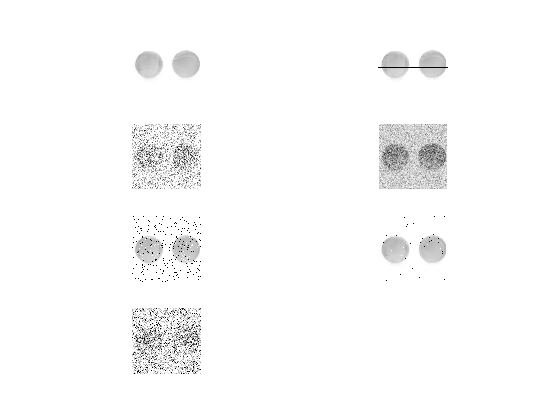

figure;
subplot(4,2,1), imshow(image_RGB); 
subplot(4,2,3), imshow(noisy_gauss);
subplot(4,2,5), imshow(noisy_salpep);
subplot(4,2,7), imshow(noisy_gauss_salpep);
subplot(4,2,2), imshow(hor_scratch);
subplot(4,2,4), imshow(smoothed_img_gauss);
subplot(4,2,6), imshow(smoothed_img_salpep);